%%%% HW 2

## Problem 12c - w/ new Type III BC + JACOBI

Engs105, W24 - Prof. Paulsen

### Numerical Solution

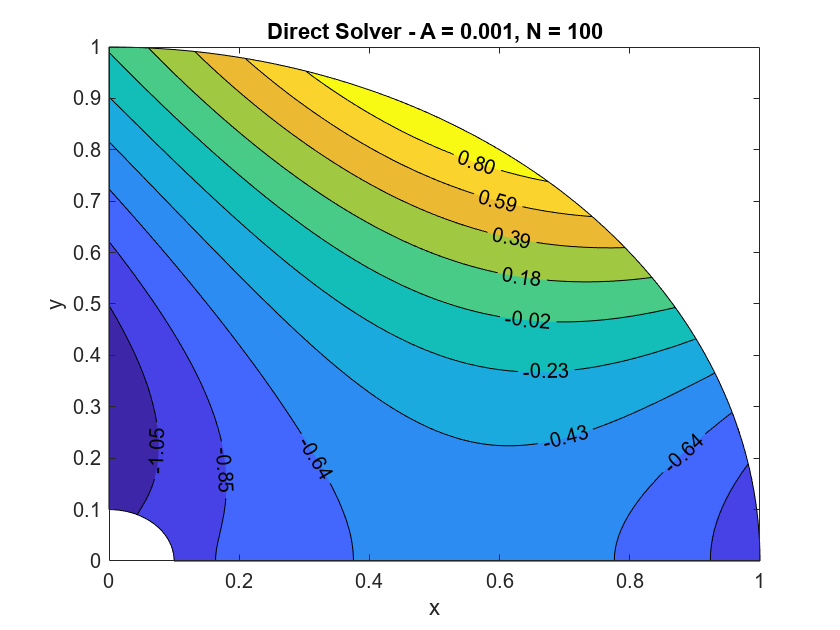

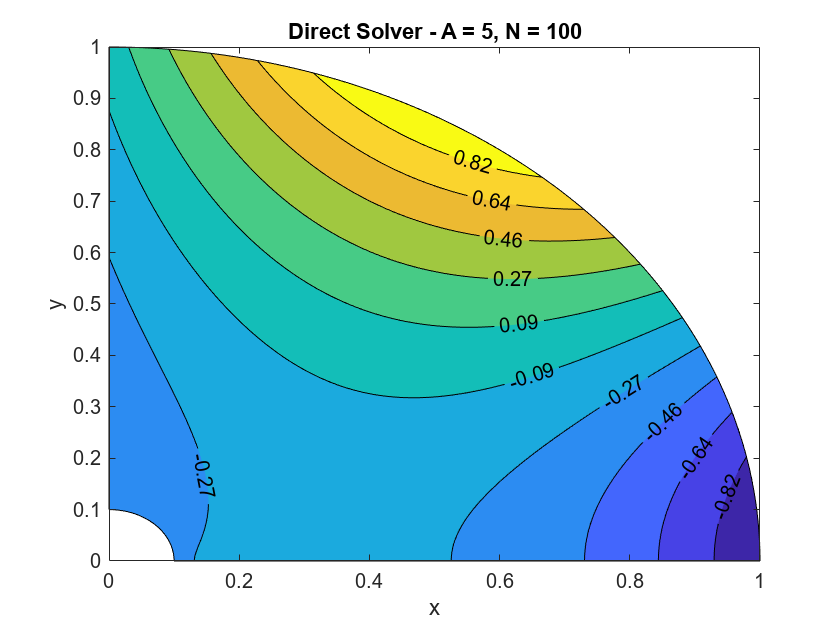

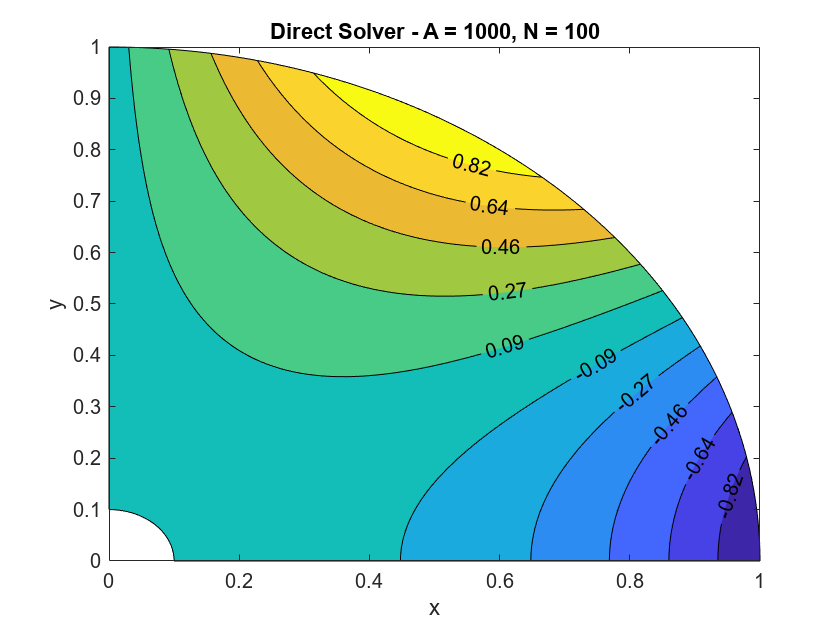

Unrecognized function or variable 'RMS_Errors'.

clear; close all
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;

ARange = [991, 5, 1000];
NRange = [100];

for jj = [1:length(ARange)]
    for ii = [1:length(NRange)]
    
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %% Plotting
        A = ARange(jj);
        N = NRange(ii);
       
        % Ranges for independent variables
        r_range = linspace(a, R, N);
        th_range = linspace(0, th_final, N);
        r_mesh = repmat(r_range, N, 1);
        th_mesh = repmat(th_range', 1, N);
        x_coor = r_mesh .* cos(th_mesh);
        y_coor = r_mesh .* sin(th_mesh);
        filename = ['iter' num2str(ARange(jj)) '.txt'];
        X_vector = readmatrix(filename);
        
        X_mesh = reshape(X_vector, [N, N]);
        X_mesh = X_mesh';
        
        figure
        contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
        hold on
        plot(zeros(N, 1), linspace(a, R, N), 'k')
        plot(linspace(a, R, N), zeros(N, 1), 'k')
        plot(a*cos(th_range), a*sin(th_range), 'k')
        plot(R*cos(th_range), R*sin(th_range), 'k')
        if A==991
            title_str = ['Direct Solver - A = 0.001, N = ' num2str(N)];
            file_str = ['A991_N' num2str(N) '.png'];
        else
            title_str = ['Direct Solver - A = ' num2str(A) ', N = ' num2str(N)];
            file_str = ['A' num2str(A) 'N' num2str(N) '.png'];
        end
        title(title_str)
        xlabel('x')
        ylabel('y')
        exportgraphics(gcf, file_str, 'Resolution', 300)

    end
end